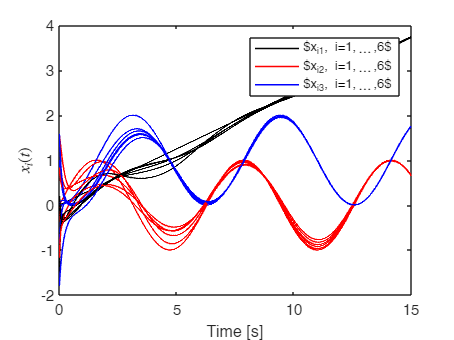

global L d n n_a dist Lb
n = 6; 
n_a =1; n_b = n - n_a;
m = 8;
d = 3;
gamma = 1;
rng(3);

s = [1 1 2 2 3 3 4 5];
t = [2 4 3 5 4 6 5 6];
G = graph(s,t);
H = incidence(G)'*eye(6);
A12 = [1 0 0; 0 2 1; 0 1 2];
A25 = eye(3); A34 = A25;
A14 = [2 2 0; 2 2 0; 0 0 1];
A36 = A14;
A23 = [2 0 0; 0 0 0; 0 0 1];
A56 = A23;
A45 = [0 0 0; 0 1 0; 0 0 2];

W = blkdiag(A12,A14,A23,A25,A34,A36,A45,A56);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
dist = [0.25;1;1];
x0 = [0;0;0;0;1;0;0;0;1;4*(rand(d*(n-3),1)-0.5)];
% dhat0 = rand(d*n_b,1);
r0 = [x0;zeros(d*n_b,1)];
options = odeset('RelTol',1e-7,'AbsTol',1e-6);

% Consensus
[t,r] = ode45(@adaptObsvConsensus,[0:0.01:15],r0,options);
r = r';
x = r(1:d*n,:);
z = r(d*n+1:d*(n+n_b),:);
dhat = zeros(d*n_b,length(t));
Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];

e = zeros(length(t),1);
for i=1:length(t)
    ui = Z*L*x(:,i);
    e(i,1) = norm(ui);
    dhat(:,i) = -z(:,i) - gamma*kron(eye(n_b),diag([1;sin(t(i));cos(t(i))]))*ui(d*n_a+1:d*n,1);
end

figure
hold on;
for i=1:n
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel('$x_i(t)$','Interpreter','latex');
box on;
legend({'$x_{i1}, i=1,\ldots,6$','$x_{i2}, i=1,\ldots,6$','$x_{i3}, i=1,\ldots,6$'},"NumColumns",1)

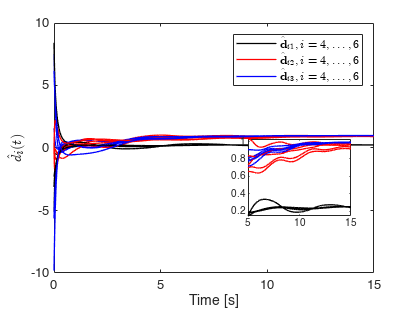


figure
hold on;
for i=1:n-n_a
   plot(t,dhat(3*i-2,:),'-k','LineWidth',1);
   plot(t,dhat(3*i-1,:),'-r','LineWidth',1);
   plot(t,dhat(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel('$\hat{d}_i(t)$','Interpreter','latex');
box on;
legend({'$\hat{\mathbf{d}}_{i1}, i=4,\ldots,6$','$\hat{\mathbf{d}}_{i2}, i=4,\ldots,6$','$\hat{\mathbf{d}}_{i3}, i=4,\ldots,6$'},...
    'Interpreter','latex',"NumColumns",1)
ax = axes('position',[0.6 .3 .25 .25]);
box on % put box around new pair of axes
hold on
indexOfInterest = (t <= 15) & (t >= 5); % range of t near perturbation
for i=1:n-n_a
plot(t(indexOfInterest),dhat(3*i-2,indexOfInterest),"-k","LineWidth",1); % hold on % plot on new axes
plot(t(indexOfInterest),dhat(3*i-1,indexOfInterest),"-r","LineWidth",1); % plot on new axes
plot(t(indexOfInterest),dhat(3*i,indexOfInterest),"-b","LineWidth",1); % plot on new axes
end
ylim([0,1.2])
axis tight
box on;

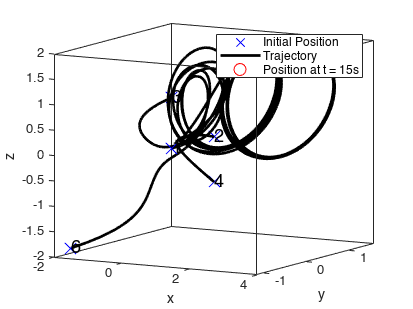



figure
hold on;
for i=1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
legend({'Initial Position','Trajectory','Position at t = 15s'}, "NumColumns", 1)
view(30,10)

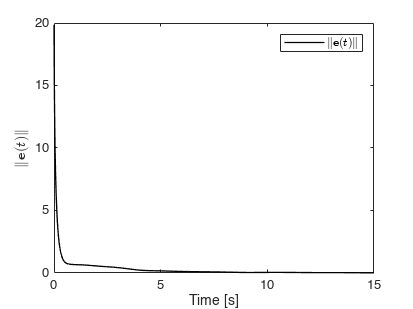


figure
hold on;
plot(t, e, '-k', 'LineWidth', 1);
xlabel 'Time [s]'; ylabel('$\|\mathbf{e}(t)\|$','Interpreter','latex');
box on;
legend({'$\|\mathbf{e}(t)\|$'}, "NumColumns", 1, 'interpreter', 'latex');

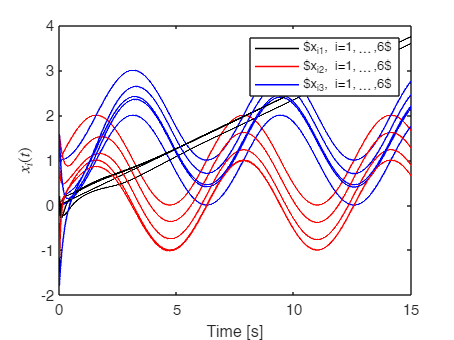

% Multiple leaders
n_a = 3; n_b = n - n_a;
r0 = [x0;zeros(d*n_b,1)];

[t,r] = ode45(@adaptObsvConsensus,[0:0.01:15],r0,options);
r = r';
x = r(1:d*n,:);
z = r(d*n+1:d*(n+n_b),:);
dhat = zeros(d*n_b,length(t));
Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];

e = zeros(length(t),1);
for i=1:length(t)
    ui = Z*L*x(:,i);
    e(i,1) = norm(ui);
    dhat(:,i) = -z(:,i) - gamma*kron(eye(n_b),diag([1;sin(t(i));cos(t(i))]))*ui(d*n_a+1:d*n,1);
end

figure
hold on;
for i=1:n
   plot(t,x(3*i-2,:),'-k','LineWidth',1);
   plot(t,x(3*i-1,:),'-r','LineWidth',1);
   plot(t,x(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel('$x_i(t)$','Interpreter','latex');
box on;
legend({'$x_{i1}, i=1,\ldots,6$','$x_{i2}, i=1,\ldots,6$','$x_{i3}, i=1,\ldots,6$'},"NumColumns",1)

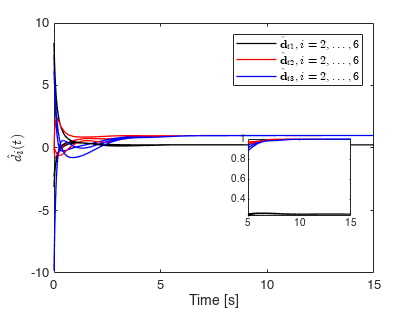


figure
hold on;
for i=1:n-n_a
   plot(t,dhat(3*i-2,:),'-k','LineWidth',1);
   plot(t,dhat(3*i-1,:),'-r','LineWidth',1);
   plot(t,dhat(3*i,:),'-b','LineWidth',1);
end
xlabel 'Time [s]'; ylabel('$\hat{d}_i(t)$','Interpreter','latex');
box on;
legend({'$\hat{\mathbf{d}}_{i1}, i=2,\ldots,6$','$\hat{\mathbf{d}}_{i2}, i=2,\ldots,6$','$\hat{\mathbf{d}}_{i3}, i=2,\ldots,6$'},...
    'Interpreter','latex',"NumColumns",1)
ax = axes('position',[0.6 .3 .25 .25]);
box on % put box around new pair of axes
hold on
indexOfInterest = (t <= 15) & (t >= 5); % range of t near perturbation
for i=1:n-n_a
plot(t(indexOfInterest),dhat(3*i-2,indexOfInterest),"-k","LineWidth",1); % hold on % plot on new axes
plot(t(indexOfInterest),dhat(3*i-1,indexOfInterest),"-r","LineWidth",1); % plot on new axes
plot(t(indexOfInterest),dhat(3*i,indexOfInterest),"-b","LineWidth",1); % plot on new axes
end
ylim([0,1.2])
axis tight
box on;

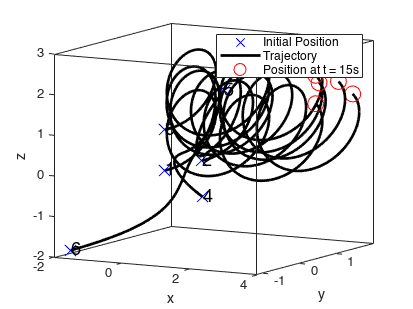


figure
hold on;
for i=1:n
   plot3(x(3*i-2,1),x(3*i-1,1),x(3*i,1),'xb','MarkerSize',12);
   plot3(x(3*i-2,:),x(3*i-1,:),x(3*i,:),'-k','LineWidth',2);
   plot3(x(3*i-2,end),x(3*i-1,end),x(3*i,end),'or','MarkerSize',12);
   text(x(3*i-2,1),x(3*i-1,1),x(3*i,1),num2str(i),"FontSize",14);
end
xlabel 'x'; ylabel 'y'; zlabel 'z';
ax = gca;
ax.BoxStyle = 'full';
box on
line([x(1,end),x(4,end)],[x(2,end),x(5,end)],[x(3,end),x(6,end)],'LineStyle','--');
line([x(1,end),x(7,end)],[x(2,end),x(8,end)],[x(3,end),x(9,end)],'LineStyle','--');
line([x(7,end),x(4,end)],[x(8,end),x(5,end)],[x(9,end),x(6,end)],'LineStyle','--');

legend({'Initial Position','Trajectory','Position at t = 15s'}, "NumColumns", 1)
view(30,10)

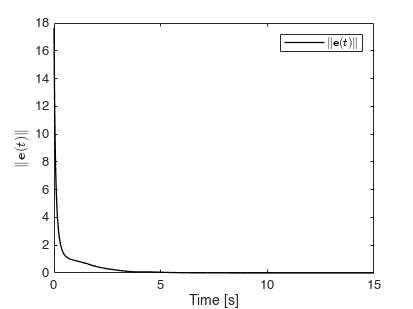


figure
hold on;
plot(t, e, '-k', 'LineWidth', 1);
xlabel 'Time [s]'; ylabel('$\|\mathbf{e}(t)\|$','Interpreter','latex');
box on;
legend({'$\|\mathbf{e}(t)\|$'}, "NumColumns", 1, 'interpreter', 'latex');

function dr = adaptObsvConsensus(t, r)
    global L d n n_a dist
    n_b = n - n_a;
    k = 1.5; gamma = 2;
    phi = [1 0 0;0 cos(t) 0;0 0 sin(t)];
    dphi = [0 0 0;0 -sin(t) 0;0 0 cos(t)];
    v_ref = phi*dist;     % Helical motion along the x-axis
    %Lb = L(d*n_a+1:end,d*n_a+1:end);
    Z = [zeros(n_a*d,n*d); zeros(n_b*d,n_a*d) eye(d*n_b)];
    x = r(1:d*n,1);
    z = r(d*n+1:d*(n+n_b),1);
    ui = -Z*L*x;
    hatd = -z + gamma*kron(eye(n_b),phi)'*ui(d*n_a+1:end,1);
    ut = Z*L*(ui);
    dz = -gamma*kron(eye(n_b),phi)'*(ut(d*n_a+1:end,1))+gamma*kron(eye(n_b),dphi)'*ui(d*n_a+1:end,1);
    dx = Z*(-k*L*x + [zeros(d*n_a,1); kron(eye(n_b),phi)*hatd]) + [kron(ones(n_a,1),v_ref); zeros(d*n_b,1)];
    dr = [dx; dz];
end